clear all
close all
clc

%% Parameters

a = 10;
b = 100/7;
r = 0;

tfin = 50;
u = 0;
x0 = 0.1*randn(3,1);

## Implementation

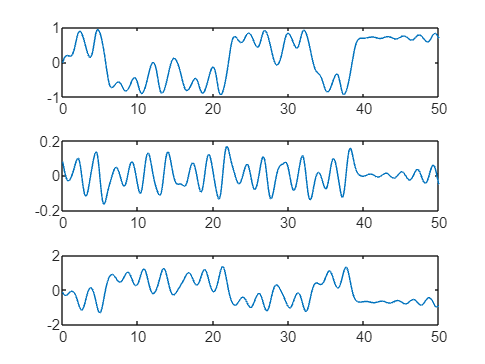


%open("chuasim")
res = sim("chuasim");
time = res.chuaOut.Time;

data = res.chuaOut.Data;
figure(1)
plot3(data(:,1), data(:,2), data(:,3))
xlabel('X1')
ylabel('Y1')
zlabel('Z1')
hold on

figure(2)
tiledlayout(3,1);
nexttile;
plot(time, data(:,1))
nexttile;
plot(time, data(:,2))
nexttile;
plot(time, data(:,3))

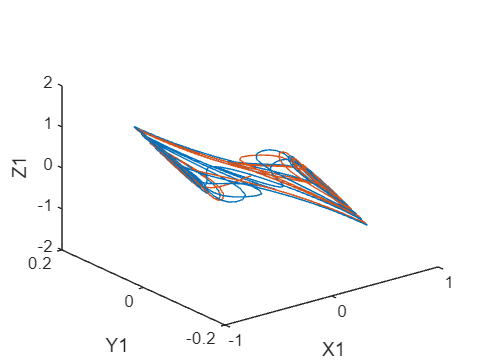


figure(1)
x0 = 0.001*randn(3,1);
%open("chuasim")
res = sim("chuasim");
data = res.chuaOut.Data;


plot3(data(:,1), data(:,2), data(:,3))

%% Equilibrium point

ep = [0,1/sqrt(2), -1/sqrt(2);0,0,0; 0,-1/sqrt(2),+1/sqrt(2) ]

ep =          0    0.7071   -0.7071
         0         0         0
         0   -0.7071    0.7071



syms x1 x2 x3 u1

p = 2* (x1^3/7) - 8*x1/7;
x = a * (x2 - x1 - p);
y = x1-x2 + x3 + u1;
z = -b*x2 - 0*x3;

A = jacobian([x,y,z],[x1,x2,x3]);
A1 = double(subs(A, [x1, x2, x2], ep(:,1)'));
A2 = double(subs(A, [x1, x2, x2], ep(:,2)'));
A3 = double(subs(A, [x1, x2, x2], ep(:,3)'));

B = jacobian([x,y,z], u1);
B1 = double(subs(B, [u1],u));
B2 = double(subs(B, [u1], u));
B3 = double(subs(B, [u1], u));

eig1 = eig(A1);
eig2 = eig(A2);
eig3 = eig(A3);

disp("The all 3 equilibrium point are unstable");

The all 3 equilibrium point are unstable


## Excercise 3


x0 = ep(:,3) + 0.01*randn(3,1)

x0 =    -0.7032
    0.0045
    0.7058


res = sim("chuasim");
time = res.chuaOut.Time;
data = res.chuaOut.Data;
figure(3)
plot3(data(:,1), data(:,2), data(:,3))
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
plot3(0,0,0, 'ro', 'MarkerSize', 3);
x0 = ep(:,2) + 0.01*randn(3,1)

x0 =     0.7089
   -0.0048
   -0.6985


res = sim("chuasim");
time = res.chuaOut.Time;
data = res.chuaOut.Data;
plot3(data(:,1), data(:,2), data(:,3))
hold on
plot3(ep(1,2),ep(2,2),ep(3,2), 'ko', 'MarkerSize',3)
x0 = ep(:,3) + 0.01*randn(3,1)

x0 =    -0.7207
    0.0046
    0.6986


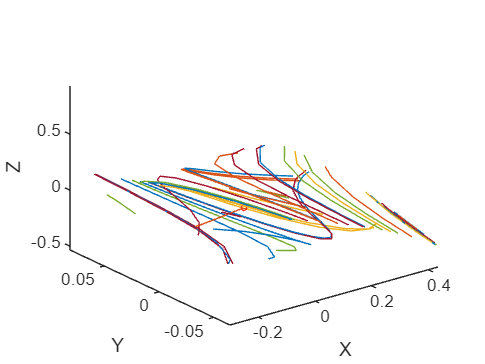

res = sim("chuasim");
time = res.chuaOut.Time;
data = res.chuaOut.Data;
plot3(data(:,1), data(:,2), data(:,3))
plot3(ep(1,3),ep(2,3),ep(3,3), 'co', 'MarkerSize',3)

## Excercise 4


eig_des = [-5, -10, -7.5]'

eig_des =    -5.0000
  -10.0000
   -7.5000


equilibrium_point = ep(:,1)';
A1= [10/7 10 0; 1 -1 1; 0 -100/7 0]

A1 =     1.4286   10.0000         0
    1.0000   -1.0000    1.0000
         0  -14.2857         0


B =[0 1 0]'

B =      0
     1
     0


K = place(A1,B,eig_des)

K =    46.9184   22.9286   19.3750



%open("chuasimcontrol")
res_c = sim("chuasimcontrol")

Error in 'chuasimcontrol/Interpreted MATLAB Function'. Evaluation of expression resulted in an invalid output. Only finite double vector or matrix outputs are supported

stable_time = res_c.chuaOutStable.time;
stable_data = res_c.chuaOutStable.data;
hold off
figure(4)
plot3(stable_data(:,1), stable_data(:,2), stable_data(:,3))
xlabel('X')
ylabel('Y')
zlabel('Z')






